# Example: Estimate 2-D Target States with Angle and Range Measurements Using `trackingEKF`

## Initialize Estimation Model

Assume a target moves in 2D with the following initial position and velocity. The simulation lasts 20 seconds with a sample time of 0.2 seconds.

rng(2022);    % For repeatable results
dt = 0.2;     % seconds
simTime = 20; % seconds
tspan = 0:dt:simTime;
trueInitialState = [30; 1; 40; 1]; % [x;vx;y;vy]
initialCovariance = diag([100,1e3,100,1e3]);
processNoise = diag([0; .01; 0; .01]); % Process noise matrix

Assume the measurements are the azimuth angle relative to the positive-x direction and the range from the origin to the target. The measurement noise covariance matrix is:

measureNoise = diag([2e-6;1]); % Measurement noise matrix. Units are m^2 and rad^2.

Preallocate variables in which to save results.

numSteps = length(tspan);
trueStates = NaN(4,numSteps);
trueStates(:,1) = trueInitialState;
estimateStates = NaN(size(trueStates));
measurements = NaN(2,numSteps);

## Obtain True States and Measurements

Propagate the constant velocity model and generate the measurements with noise. 

for i = 2:length(tspan)
    if i ~= 1
        trueStates(:,i) = stateModel(trueStates(:,i-1),dt) + sqrt(processNoise)*randn(4,1);  
    end
    measurements(:,i) = measureModel(trueStates(:,i)) + sqrt(measureNoise)*randn(2,1);
end

Plot the true trajectory and the measurements.

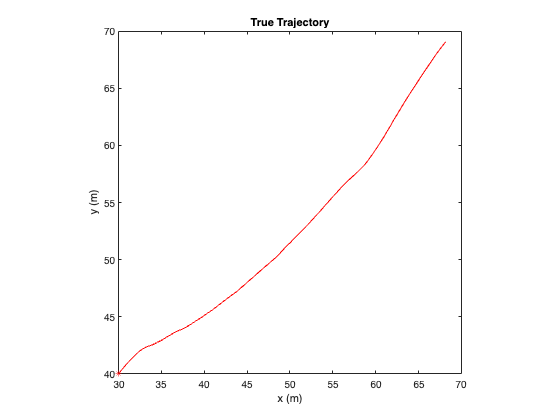

figure(1)
plot(trueStates(1,1),trueStates(3,1),"r*",DisplayName="Initial Truth")
hold on
plot(trueStates(1,:),trueStates(3,:),"r",DisplayName="True Trajectory")
xlabel("x (m)")
ylabel("y (m)")
title("True Trajectory")
axis square

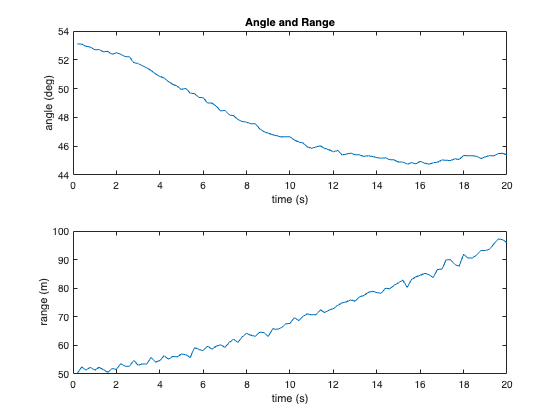

figure(2)
subplot(2,1,1)
plot(tspan,measurements(1,:)*180/pi)
xlabel("time (s)")
ylabel("angle (deg)")
title("Angle and Range")
subplot(2,1,2)
plot(tspan,measurements(2,:))
xlabel("time (s)")
ylabel("range (m)")

## Initialize Extended Kalman Filter

Initialize the filter with an initial state estimate at `[35; 0; 45; 0]`.

filter = trackingEKF(State=[35; 0; 45; 0],StateCovariance=initialCovariance, ...
    StateTransitionFcn=@stateModel,ProcessNoise=processNoise, ...
    MeasurementFcn=@measureModel,MeasurementNoise=measureNoise);
estimateStates(:,1) = filter.State;

## Run Extended Kalman Filter And Show Results

Run the filter by recursively calling the `predict` and `correct` object functions. 

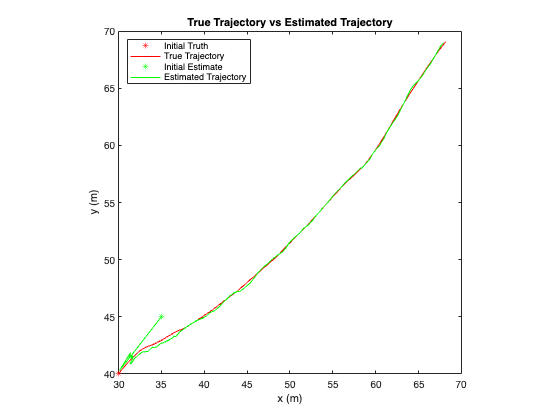

for i=2:length(tspan)
    predict(filter,dt);
    estimateStates(:,i) = correct(filter,measurements(:,i));
end
figure(1)
plot(estimateStates(1,1),estimateStates(3,1),"g*",DisplayName="Initial Estimate")
plot(estimateStates(1,:),estimateStates(3,:),"g",DisplayName="Estimated Trajectory")
legend(Location="northwest")
title("True Trajectory vs Estimated Trajectory")

## Helper Functions

`stateModel` modeled constant velocity motion without process noise.

function stateNext = stateModel(state,dt)
    F = [1 dt 0  0; 
         0  1 0  0;
         0  0 1 dt;
         0  0 0  1];
    stateNext = F*state;
end

`meausreModel` models range and azimuth angle measurements without noise.

function z = measureModel(state)
    angle = atan(state(3)/state(1));
    range = norm([state(1) state(3)]);
    z = [angle;range];
end

*Copyright 2021 The MathWorks, Inc.*